# **Final Project**

# **Locating a Refugee Camp in Nord-Kivu, DRC**

**12/16/2016**

**Marie Parent**

## **Prepare Data**

***DRN = Do Not Run section.**

**Question: Will we will need to account for the distortion caused by longitudinal measures?**

Benchmark: 1° longitude is about 111.11 km at the equator.

Elsewhere: 1° longitude is about 111.11 km * cos(latitude).

The point in the DRC furthest from the equator has a latitude of about -13.44°, based on a quick Google Maps examination.  Converting degrees to radians (Matlab cos uses radians): 


$$Radians = Degrees(\frac{\pi}{180})$$


(111.11-111.11*cos((-13.44)*(pi/180)))/111.11 % Percentage distortion

111.11-111.11*cos((-13.44)*(pi/180)) % Distortion in kilometers

a_ACLED_EventType1 = 6841x1 struct array with fields:

    GWNO
    EVENT_ID_C
    EVENT_ID_N
    EVENT_DATE
    YEAR
    TIME_PRECI
    EVENT_TYPE
    ACTOR1
    ALLY_ACTOR
    INTER1
    ACTOR2
    ALLY_ACT_1
    INTER2
    INTERACTIO
    COUNTRY
    ADMIN1
    ADMIN2
    ADMIN3
    LOCATION
    LATITUDE
    LONGITUDE
    GEO_PRECIS
    SOURCE
    NOTES
    FATALITIES


s_ACLED_EventType1 = 6841x1 struct array with fields:

    Geometry
    Lon
    Lat


A1 =    25.8500   -9.2000
   28.8966   -8.4716
   28.4667   -3.0000
   29.5958   -1.2981
   29.4461   -1.1869
   28.7854   -2.4802
   29.4461   -1.1869
   29.6237   -0.7369
   29.5000    4.1667
   29.6237   -0.7369


B1 =    12.3494   -5.9342
   12.4666   -5.9666
   12.7666   -5.8166
   12.9393   -4.9898
   13.0188   -5.4902
   13.0503   -5.8468
   13.0667   -5.7000
   13.0698   -5.8399
   13.2667   -5.3333
   13.4443   -5.7691


A =      1     1
     6     1
     3     2
     2     1
     6     1
     3     2


B =      1     1
     2     1
     3     2
     6     1


B2 =     '1 1'
    '2 1'
    '3 2'
    '6 1'


Distances at the southernmost point of the DRC versus points at the equator in the DRC will be distorted about 2.74%, or about 3.04 kilometers.

**Answer: No.**  This distortion is small enough relative to the overall precision of the datasets that we are working with that it would not be helpful to account for distortion caused by longitudinal measures.

**(DNR) ACLED Data**

clear; clf;
cd '/Users/marieparent/Documents/MATLAB/Final Project R1/ACLED-Version-6'
[s_ACLED,a_ACLED] = shaperead('ACLED_Version6_Shpfile.shp', 'UseGeoCoords', true);

% Filter by country (the DRC, i.e. GWNO==490) and Year (2006-2015)
toKeep = [a_ACLED.GWNO]==490 & ([a_ACLED.YEAR]==2006 | [a_ACLED.YEAR]==2007 | [a_ACLED.YEAR]==2008 | [a_ACLED.YEAR]==2009 | [a_ACLED.YEAR]==2010 | [a_ACLED.YEAR]==2011 |[a_ACLED.YEAR]==2012 | [a_ACLED.YEAR]==2013 | [a_ACLED.YEAR]==2014 | [a_ACLED.YEAR]==2015);
a_ACLED(toKeep==0,:) = [];
s_ACLED(toKeep==0,:) = [];
clear toKeep;

cd '/Users/marieparent/Documents/MATLAB/Final Project'
save('ACLED_DRC_2006_2015')

**(DNR) Ethnic Group Polygon Data**

clear; clf;
cd '/Users/marieparent/Documents/MATLAB/Final Project R1/GeoEPR-2014'
[s_GeoEPR,a_GeoEPR] = shaperead('GeoEPR-2014.shp', 'UseGeoCoords', true);

% Filter by the DRC and ethnic groups relevant to our time period (i.e., current groups recorded as active until 2013)
% Note that there were some polygons that were improperly recorded and therefore unusable in the data.
% However, none of these appeared to be in the DRC.
toKeep = strcmp({a_GeoEPR.statename},'Congo, DRC') & [a_GeoEPR.to]==2013;
a_GeoEPR(toKeep==0,:) = [];
s_GeoEPR(toKeep==0,:) = [];
clear toKeep;

cd '/Users/marieparent/Documents/MATLAB/Final Project'
save('GeoEPR_DRC_CurrentGroups')

**(DNR) Cities Data**

clear;
cd '/Users/marieparent/Documents/MATLAB/Final Project R1/DRC Cities Homemade'
% Import by going to Home --> Import Data

s_Cities = table2struct(table(Lat,Lon))

s_Cities = 39x1 struct array with fields:

    Lat
    Lon


a_Cities = table2struct(table(Name,Province,Population,Top30CitybyPop,Capital,CorrectedfromWikipedia))

a_Cities = 39x1 struct array with fields:

    Name
    Province
    Population
    Top30CitybyPop
    Capital
    CorrectedfromWikipedia


clear Capital CorrectedfromWikipedia Lat Lon Name Population Province Top30CitybyPop

cd '/Users/marieparent/Documents/MATLAB/Final Project'
save('Cities_DRC')

## **ACLED Data - Aggregating by Location**

**(DNR) **

clear;
cd '/Users/marieparent/Documents/MATLAB/Final Project'
load('ACLED_DRC_2006_2015')

**(DNR) Create a Matrix with Event Counts by Event_Type**

% Step 1: Create a list of all the different counts we want
EventType = {'Battle-No change of territory' 'Battle-Non-state actor overtakes territory' 'Battle-Government regains territory' 'Headquarters or base established' 'Strategic development' 'Riots/Protests' 'Violence against civilians' 'Non-violent transfer of territory' 'Remote violence'};

% Step 2: Create new vector of unique Lon/Lat values
OriginalLonLat = [[s_ACLED.Lon]',[s_ACLED.Lat]'];
UniqueLonLat = unique(OriginalLonLat,'rows');

% Steps 3-7
for k = 1:length(EventType)
    % Step 3: Filter original data
        % a: Create duplicate original data for filtering
    s_ACLED_filtered = s_ACLED;
        % b: Filter duplicate original data
    toKeep = strcmp({a_ACLED.EVENT_TYPE},EventType(k));
    s_ACLED_filtered(toKeep==0,:) = [];
    clear toKeep;

    % Step 4: A1 = Vector with all Event Type X Lat/Lon Listings
    A1 = [[s_ACLED_filtered.Lon]' [s_ACLED_filtered.Lat]'];
    B1 = UniqueLonLat;

    % Step 5: Put Lon/Lat in one column - NonUnique Vector A
    for i = 1:length(A1);
        A2(i) = {[num2str(A1(i,1)) ' ' num2str(A1(i,2))]};
    end
    A2 = A2';

    % Step 6: Put Lon/Lat in one column - Unique Vector B
    for i = 1:length(B1);
        B2(i) = {[num2str(B1(i,1)) ' ' num2str(B1(i,2))]};
    end
    B2 = B2';

    % Step 7: Count Events (Vector A) per Location (Vector B)
    cd '/Users/marieparent/Documents/MATLAB/Final Project/countmember'
    Count_EventType(:,k) = countmember(B2,A2);

end
clear A1 A2 B1 B2 s_ACLED_filtered i k OriginalLonLat

**(DNR) Create a Vector with Event Counts**

Count = sum(Count_EventType,2);

**(DNR) Create a Matrix with Event Counts by Actor1 or Actor2 is DRC Rioters or Protesters**

Note that there are 21 cases taht are not the actors 'Rioters (Democratic Republic of Congo)' or 'Protesters (Democratic Republic of Congo).'  I have purposefully excluded these events from the analysis.  Includes 24 acts that are Event_Type = 'Violence against civilians,' rather than 'Riots/Protests.'

% Step 1: Create a list of all the different counts we want
RiotersProtestersDRC = {'Rioters (Democratic Republic of Congo)' 'Protesters (Democratic Republic of Congo)'};

% Step 2: Create new vector of unique Lon/Lat values
OriginalLonLat = [[s_ACLED.Lon]',[s_ACLED.Lat]'];
UniqueLonLat = unique(OriginalLonLat,'rows');

% Steps 3-7
for k = 1:length(RiotersProtestersDRC)
    % Step 3: Filter original data
        % a: Create duplicate original data for filtering
    s_ACLED_filtered = s_ACLED;
        % b: Filter duplicate original data
    toKeep = strcmp({a_ACLED.ACTOR1},RiotersProtestersDRC(k)) | strcmp({a_ACLED.ACTOR2},RiotersProtestersDRC(k));
    s_ACLED_filtered(toKeep==0,:) = [];
    clear toKeep;

    % Step 4: A1 = Vector with all Rioters/Protesters Lat/Lon Listings
    A1 = [[s_ACLED_filtered.Lon]' [s_ACLED_filtered.Lat]'];
    B1 = UniqueLonLat;

    % Step 5: Put Lon/Lat in one column - NonUnique Vector A
    for i = 1:length(A1);
        A2(i) = {[num2str(A1(i,1)) ' ' num2str(A1(i,2))]};
    end
    A2 = A2';

    % Step 6: Put Lon/Lat in one column - Unique Vector B
    for i = 1:length(B1);
        B2(i) = {[num2str(B1(i,1)) ' ' num2str(B1(i,2))]};
    end
    B2 = B2';

    % Step 7: Count Events (Vector A) per Location (Vector B)
    cd '/Users/marieparent/Documents/MATLAB/Final Project/countmember'
    Count_RiotersProtestersDRC(:,k) = countmember(B2,A2);

end
clear A1 A2 B1 B2 s_ACLED_filtered i k OriginalLonLat

**(DNR) Create a Matrix with Fatality Counts by Event Types**

% Step 1: Create a list of all the different counts we want
EventType = {'Battle-No change of territory' 'Battle-Non-state actor overtakes territory' 'Battle-Government regains territory' 'Headquarters or base established' 'Strategic development' 'Riots/Protests' 'Violence against civilians' 'Non-violent transfer of territory' 'Remote violence'};

% Step 2: Create new vector of unique Lon/Lat values
OriginalLonLat = [[s_ACLED.Lon]',[s_ACLED.Lat]'];
UniqueLonLat = unique(OriginalLonLat,'rows');

% Steps 3-4
for k = 1:length(EventType);
    % Step 3: Filter original data
        % a: Create duplicate original data for filtering
    s_ACLED_filtered = s_ACLED;
    a_ACLED_filtered = a_ACLED;
        % b: Filter duplicate original data
    toKeep = [a_ACLED.FATALITIES]>0 & strcmp({a_ACLED.EVENT_TYPE},EventType(k));
    s_ACLED_filtered(toKeep==0,:) = [];
    a_ACLED_filtered(toKeep==0,:) = [];
    clear toKeep;

    % Step 4: Sum Fatalities by location
    for i = 1:length(UniqueLonLat);
        % Step: Filter filtered data
            % a: Create duplicate filtered data for location filtering
        s_ACLED_LocFilter = s_ACLED_filtered;            
        a_ACLED_LocFilter = a_ACLED_filtered;
            % b: Filter duplicate filtered data by location
        toKeep = UniqueLonLat(i,1)==[s_ACLED_filtered.Lon] & UniqueLonLat(i,2)==[s_ACLED_filtered.Lat];
        s_ACLED_LocFilter(toKeep==0,:) = [];
        a_ACLED_LocFilter(toKeep==0,:) = [];
        clear toKeep;
        FatalCount_EventType(i,k) = sum([a_ACLED_LocFilter.FATALITIES]);
    end
                
end
clear A1 A2 B1 B2 i k OriginalLonLat s_ACLED_filtered s_ACLED_LocFilter a_ACLED_filtered a_ACLED_LocFilter

**(DNR) Create a Matrix with Fatality Counts**

FatalCount = sum(FatalCount_EventType,2);
clear a_ACLED s_ACLED

**(DNR) Save Aggregated Data**

cd '/Users/marieparent/Documents/MATLAB/Final Project'
save('ACLED_Aggregated')

**(DNR) Road Data filtered for Nord-Kivu**

% Load Road Data
clear;
cd '/Users/marieparent/Documents/MATLAB/Final Project/COD_rds';
[s_Roads,a_Roads] = shaperead('COD_roads.shp', 'UseGeoCoords', true);

% The Road network is the heaviest set of data
% Trim Road network for Nord-Kivu by deleting any data outside of [26.5 30.5 -2.5 1.5]

% Delete points in Road polylines that are outside of axis boundaries
s_Roads_NK = s_Roads;
for i = 1:length(s_Roads);
    toKeepLon = s_Roads(i).Lon<=30.5 & s_Roads(i).Lon>=26.5;
    toKeepLat = s_Roads(i).Lat<=1.5 & s_Roads(i).Lat>=-2.5;
    toKeep = toKeepLon & toKeepLat;
    s_Roads_NK(i).Lon = s_Roads(i).Lon(toKeep);
    s_Roads_NK(i).Lat = s_Roads(i).Lat(toKeep);
end
clear toKeepLon toKeepLat toKeep

% Delete Roads that are now empty arrays for Lat or Lon
for i = 1:length(s_Roads);
    toKeep(i) = not(isempty(s_Roads_NK(i).Lon));
end
s_Roads_NK = s_Roads_NK(toKeep);
a_Roads_NK = a_Roads(toKeep);
% Note that our Roads Lat & Lon vectors no longer end in "NaNs"

clear a_Roads i s_Roads toKeep

cd '/Users/marieparent/Documents/MATLAB/Final Project'
save('Roads_NK')

**Load Data**

clear; clf;
cd '/Users/marieparent/Documents/MATLAB/Final Project';

% Conflict Data
load('ACLED_DRC_2006_2015');

% Aggregated Conflict Data
load('ACLED_Aggregated');

% Ethnic Group Polygons
load('GeoEPR_DRC_CurrentGroups');

% Cities
load('Cities_DRC');

% Roads
cd '/Users/marieparent/Documents/MATLAB/Final Project/COD_rds';
[s_Roads,a_Roads] = shaperead('COD_roads.shp', 'UseGeoCoords', true);

% Roads in Nord-Kivu
cd '/Users/marieparent/Documents/MATLAB/Final Project';
load('Roads_NK');

% Roads in Nord-Kivu with NaNs
cd '/Users/marieparent/Documents/MATLAB/Final Project';
load('Roads_NK_NaNs');

% Country Boundary
cd '/Users/marieparent/Documents/MATLAB/Final Project/COD_adm';
[s_Adm0,a_Adm0] = shaperead('COD_adm0.shp', 'UseGeoCoords', true);

% Province Boundaries (Level 1)
cd '/Users/marieparent/Documents/MATLAB/Final Project/COD_adm';
[s_Adm1,a_Adm1] = shaperead('COD_adm1.shp', 'UseGeoCoords', true);

% Province Boundaries (Level 2)
cd '/Users/marieparent/Documents/MATLAB/Final Project/COD_adm';
[s_Adm2,a_Adm2] = shaperead('COD_adm2.shp', 'UseGeoCoords', true);

## Initial Data Examination

Cities in the DRC, Scaled by 2010 Population

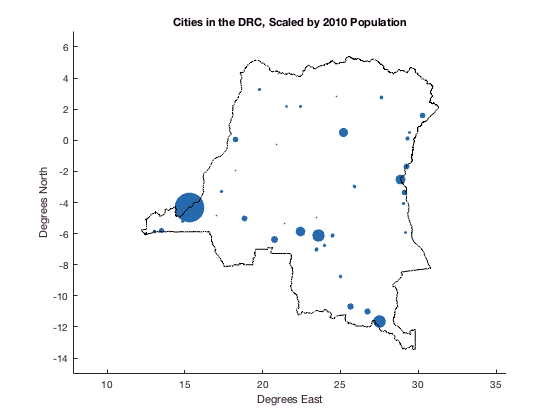

clf; figure; hold on;

% Plot all Cities, Scaled by Population
scatter([s_Cities.Lon], [s_Cities.Lat], [a_Cities.Population]/10000, [.15 .41 .68], 'filled');

% Label Kinshasa
%text([s_Cities(1).Lon]+1, [s_Cities(1).Lat], 'Kinshasa (Capital)');

% Plot Country Boundary
for i = 1:size(s_Adm0,1);
    plot(s_Adm0(i).Lon, s_Adm0(i).Lat, '-k');
end
axis([10 37 -15 7]); axis equal;
title('Cities in the DRC, Scaled by 2010 Population'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

Number of Conflicts in the DRC, 2006-2015

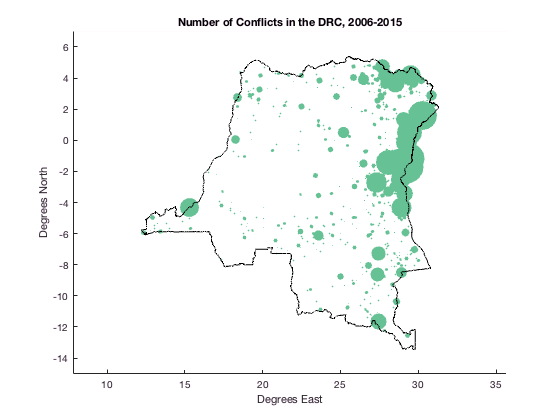

e = 1;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count(:,e)>0, 1), UniqueLonLat(Count(:,e)>0, 2), Count(Count(:,e)>0, e), [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

title('Number of Conflicts in the DRC, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');
axis([10 37 -15 7]); axis equal;

clear e i;

Conflict Fatalities in the DRC, 2006-2015

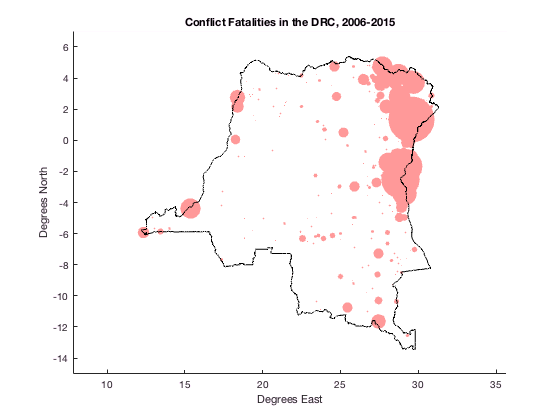

clf; figure; hold on;

% Plot Conflict Locations scaled by number of Fatalities
scatter(UniqueLonLat(FatalCount>0,1), UniqueLonLat(FatalCount>0,2), FatalCount(FatalCount>0,1), [1 .6 .6], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Conflict Fatalities in the DRC, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

Battles - No Change of Territory (EventType(1))

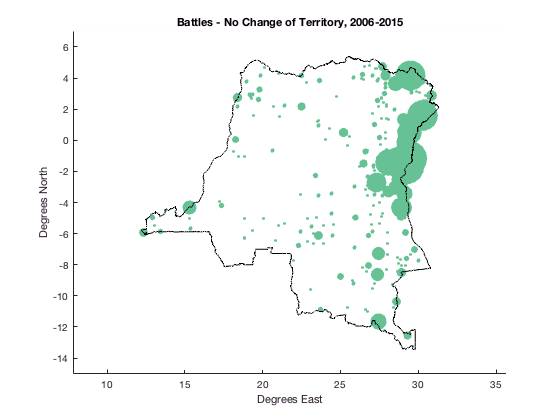

e = 1;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Battles - No Change of Territory, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Battles - Non-State Actor Overtakes Territory (EventType(2))

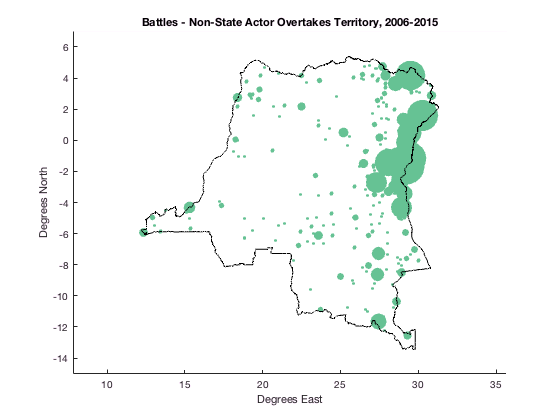

e = 2;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Battles - Non-State Actor Overtakes Territory, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Battles - Government Regains Territory (EventType(3))

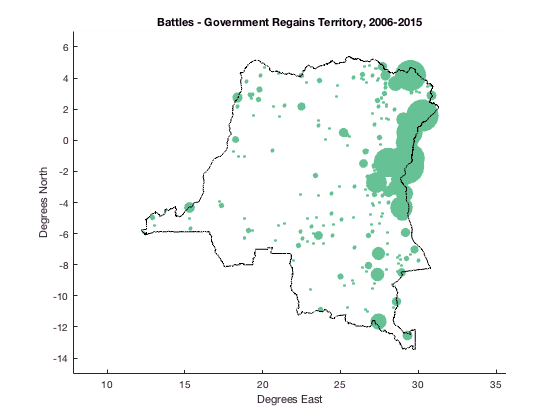

e = 3;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Battles - Government Regains Territory, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Headquarters or Base Established (EventType(4))

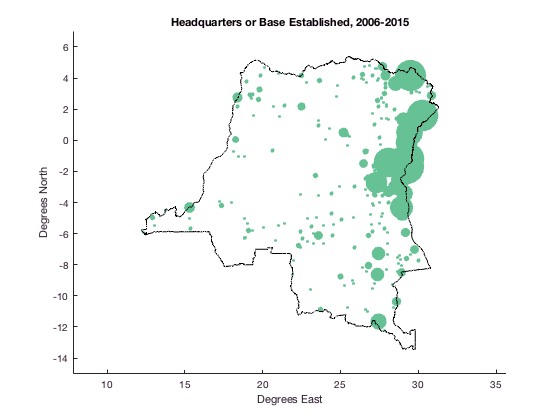

e = 4;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Headquarters or Base Established, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Strategic Development (EventType(5))

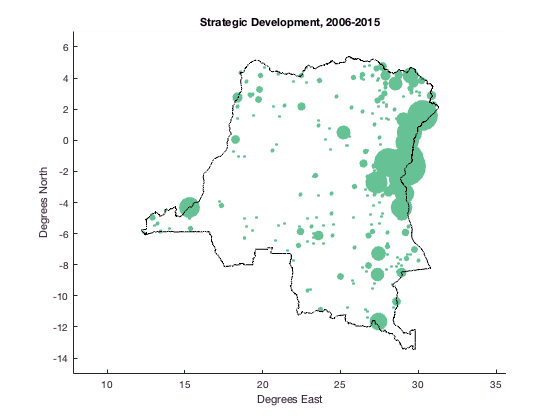

e = 5;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Strategic Development, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Riots/Protests (EventType(6))

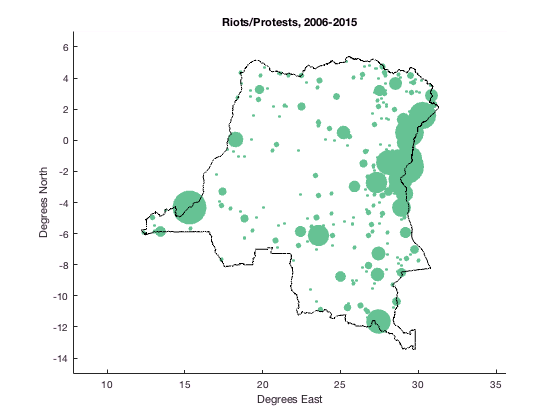

e = 6;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Riots/Protests, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Violence against Civilians (EventType(7))

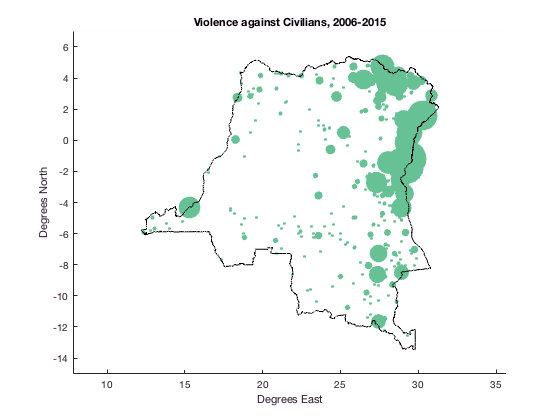

e = 7;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Violence against Civilians, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Non-Violent Transfer of Territory (EventType(8))

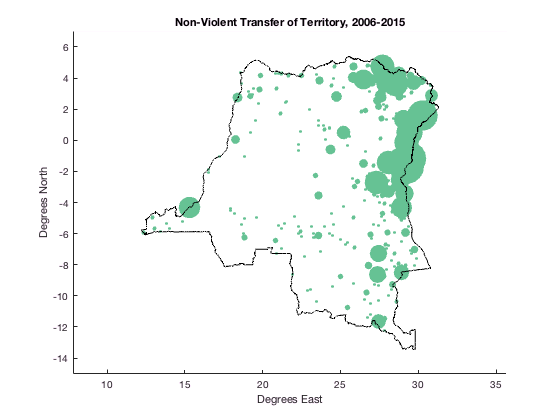

e = 8;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Non-Violent Transfer of Territory, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Remote Violence (EventType(9))

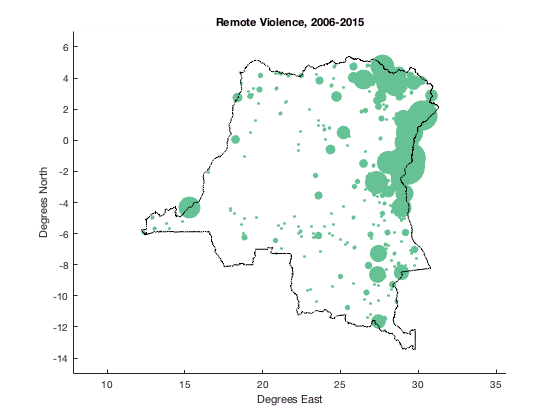

e = 9;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_EventType(:,e)>0, 1), UniqueLonLat(Count_EventType(:,e)>0, 2), Count_EventType(Count_EventType(:,e)>0, e)*10, [.4 .76 .58], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Remote Violence, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Riots (Count_RiotersProtestersDRC(1))

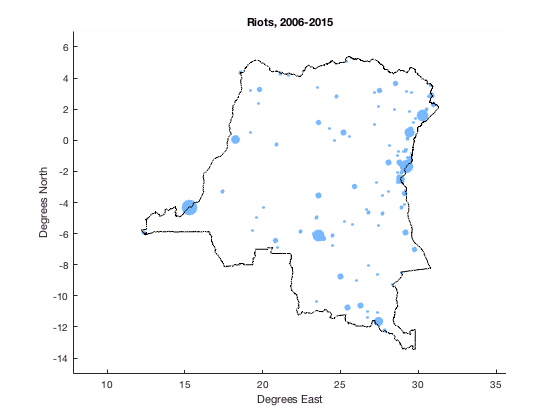

e = 1;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_RiotersProtestersDRC(:,e)>0, 1), UniqueLonLat(Count_RiotersProtestersDRC(:,e)>0, 2), Count_RiotersProtestersDRC(Count_RiotersProtestersDRC(:,e)>0, e)*10, [.47 .72 1], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Riots, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Protests (Count_RiotersProtestersDRC(1))

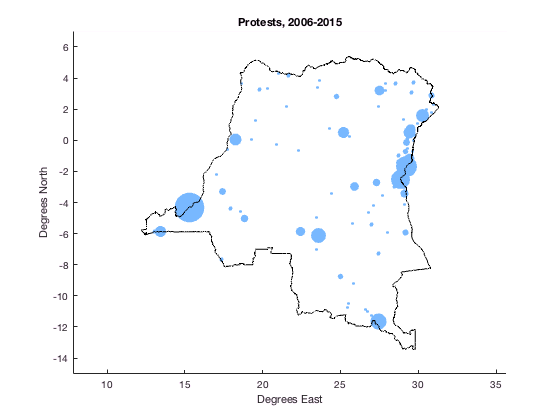

e = 2;
clf; figure; hold on;
% Plot events scaled by counts
scatter(UniqueLonLat(Count_RiotersProtestersDRC(:,e)>0, 1), UniqueLonLat(Count_RiotersProtestersDRC(:,e)>0, 2), Count_RiotersProtestersDRC(Count_RiotersProtestersDRC(:,e)>0, e)*10, [.47 .72 1], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Protests, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

clear e i;

Ethnic Group Polygons

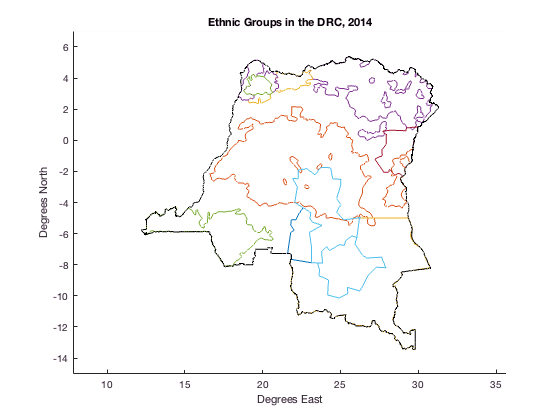

clf; hold on;

% Plot Ethnic Group Polygons
for i = 1:size(s_GeoEPR,1);
    plot(s_GeoEPR(i).Lon, s_GeoEPR(i).Lat);
    hold on;
end

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Ethnic Groups in the DRC, 2014'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

Ethnic Groups & Conflict Fatalities in the DRC, 2006-2015

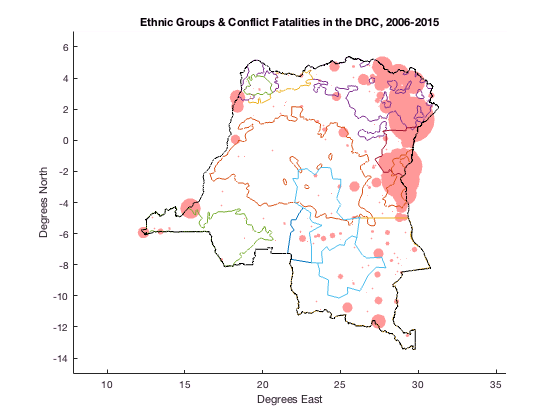

clf; figure; hold on;

% Plot Conflict Locations scaled by number of Fatalities
scatter(UniqueLonLat(FatalCount>0,1), UniqueLonLat(FatalCount>0,2), FatalCount(FatalCount>0,1), [1 .6 .6], 'filled');

% Plot Ethnic Group Polygons
for i = 1:size(s_GeoEPR,1);
    plot(s_GeoEPR(i).Lon, s_GeoEPR(i).Lat);
    hold on;
end

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Ethnic Groups & Conflict Fatalities in the DRC, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

## Nord Kivu - Using Buffers to Locate Refugee Camps Away from Conflict-Prone Locations

Conflict Fatalities around Nord-Kivu

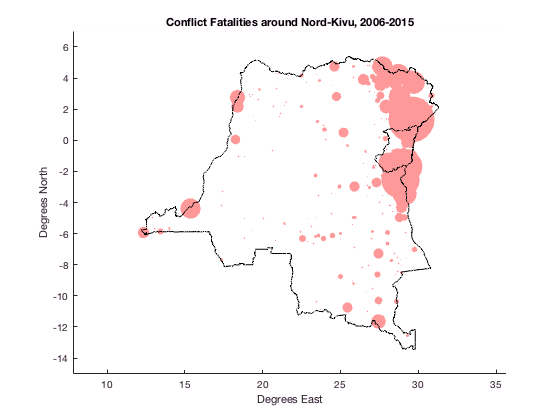

clf; figure; hold on;

% Plot Conflict Locations scaled by number of Fatalities
scatter(UniqueLonLat(FatalCount>0,1), UniqueLonLat(FatalCount>0,2), FatalCount(FatalCount>0,1), [1 .6 .6], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

% Plot Nord Kivu Boundary
plot(s_Adm2(32).Lon, s_Adm2(32).Lat, '-k');

axis([10 37 -15 7]); axis equal;
title('Conflict Fatalities around Nord-Kivu, 2006-2015'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');

A Closer Look: Nord-Kivu Conflict Fatalities

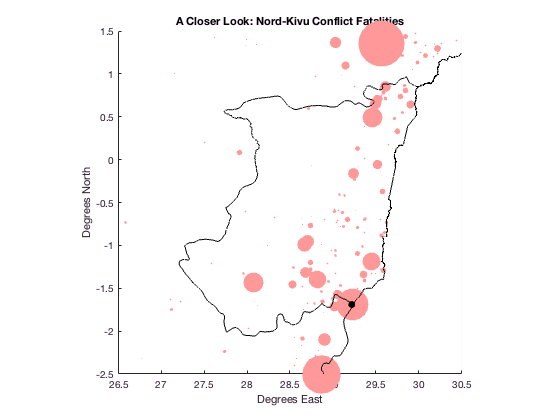

clf; figure; hold on;

% Plot Conflict Locations scaled by number of Fatalities
scatter(UniqueLonLat(FatalCount>0,1), UniqueLonLat(FatalCount>0,2), FatalCount(FatalCount>0,1), [1 .6 .6], 'filled');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

% Plot Nord Kivu Boundary
plot(s_Adm2(32).Lon, s_Adm2(32).Lat, '-k');

% Plot Goma, Capital City and Location of UNHCR Sub-Office
plot(s_Cities(10).Lon, s_Cities(10).Lat, '.k', 'MarkerSize', 20)
%text(s_Cities(10).Lon+.1, s_Cities(10).Lat, 'Goma')

title('A Closer Look: Nord-Kivu Conflict Fatalities'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');
axis([26.5 30.5 -2.5 1.5]);

A Closer Look: Nord-Kivu Conflict Fatalities with Roads

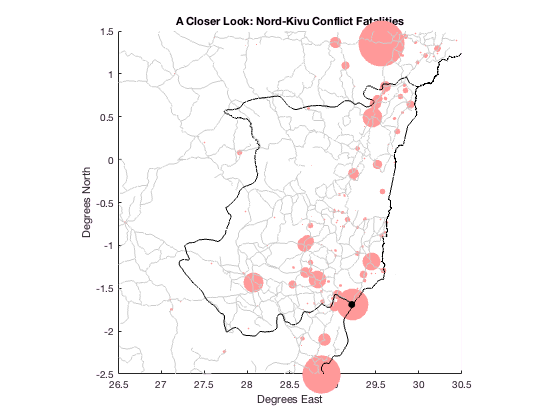

clf; figure; hold on;

% Plot Conflict Locations scaled by number of Fatalities
scatter(UniqueLonLat(FatalCount>0,1), UniqueLonLat(FatalCount>0,2), FatalCount(FatalCount>0,1), [1 .6 .6], 'filled');

% Plot Roads in Nord-Kivu Box
for i = 1:size(s_Roads_NK,1);
    plot(s_Roads_NK(i).Lon, s_Roads_NK(i).Lat, '-', 'Color', [.8 .8 .8]);
end
hold on;

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

% Plot Nord-Kivu Boundary
plot(s_Adm2(32).Lon, s_Adm2(32).Lat, '-k');

% Plot Goma, Capital City and Location of UNHCR Sub-Office
plot(s_Cities(10).Lon, s_Cities(10).Lat, '.k', 'MarkerSize', 20)
%text(s_Cities(10).Lon+.1, s_Cities(10).Lat, 'Goma')

title('A Closer Look: Nord-Kivu Conflict Fatalities'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');
axis([26.5 30.5 -2.5 1.5]);

Buffers around Chronically High-Conflict Locations in Nord-Kivu

% MARIE note to self - this part of code is broken for r = .3 or less, because there is a separate hole in the red space.
% Patch gets confused with the NaN deliminating the separate polygons and just plots this rando line :(
% Create Buffers 
r = .35; % desired radius
eventtolerance = 4; % We will buffer out any area that has both more than this many events ...
fatalitytolerance = 20; % ... and more than this many fatalities
[dangerZoneLat, dangerZoneLon] = scircle1(UniqueLonLat(Count>eventtolerance & FatalCount>fatalitytolerance,2),UniqueLonLat(Count>eventtolerance & FatalCount>fatalitytolerance,1),repmat(r, [size(UniqueLonLat(Count>eventtolerance & FatalCount>fatalitytolerance,1)),1]));
clear r eventtolerance fatalitytolerance


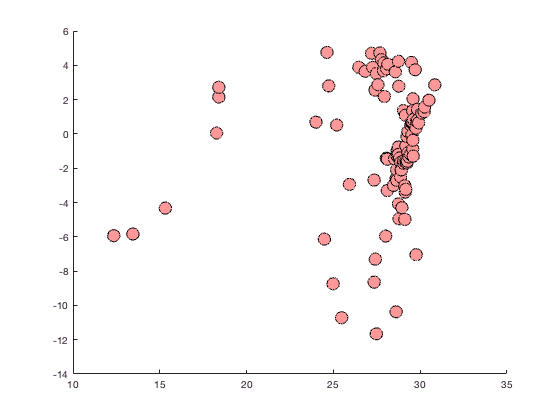

clf; figure; hold on;
% Plot Danger Zone
fill(dangerZoneLon, dangerZoneLat, [1 .6 .6]);

plot(dangerZoneLon, dangerZoneLat, [1 .6 .6]);

Error using plot
Data must be a single matrix Y or a list of pairs X,Y.



% Plot Roads in Nord-Kivu Box
for i = 1:size(s_Roads_NK,1);
    plot(s_Roads_NK(i).Lon, s_Roads_NK(i).Lat, '-', 'Color', [.8 .8 .8]);
end
hold on;

% Plot Nord-Kivu Boundary
plot(s_Adm2(32).Lon, s_Adm2(32).Lat, '-k');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

% Plot Goma, Capital City and Location of UNHCR Sub-Office
plot(s_Cities(10).Lon, s_Cities(10).Lat, '.k', 'MarkerSize', 20)
text(s_Cities(10).Lon+.1, s_Cities(10).Lat, 'Goma')

% Formatting
text(28.8,-1,'DANGER');
text(28.87,-1.15,'ZONE');
title('Danger Zone around Chronically High-Conflict Locations'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');
axis([26.5 30.5 -2.5 1.5]);

Nord-Kivu Minus Danger Buffers

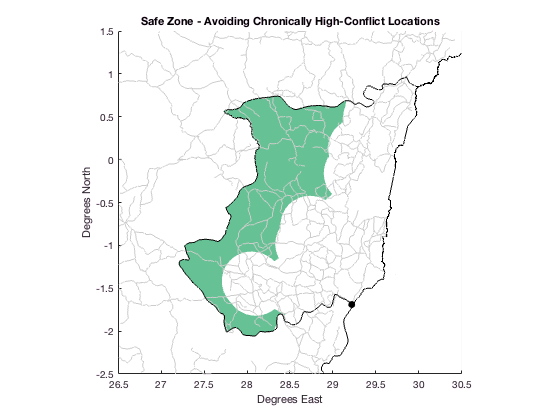

% Create Safe Zone Polygon - Negative of Danger Zone Polygon
xSafeZone = [s_Adm2(32).Lon(1,1:end-1)]';
ySafeZone = [s_Adm2(32).Lat(1,1:end-1)]';
for i = 1:size(dangerZoneLat,2);
    [xSafeZone, ySafeZone] = polybool('minus', xSafeZone, ySafeZone, dangerZoneLon(:,i), dangerZoneLat(:,i));
end

clf; figure; hold on;

% Plot Safe Zone (negative of Danger Zone)
fill(xSafeZone, ySafeZone, [.4 .76 .58]);
plot(xSafeZone, ySafeZone, '-', 'Color', [.4 .76 .58]);

% Plot Roads in Nord-Kivu Box
for i = 1:size(s_Roads_NK,1);
    plot(s_Roads_NK(i).Lon, s_Roads_NK(i).Lat, '-', 'Color', [.8 .8 .8]);
end
hold on;

% Plot Nord-Kivu Boundary
plot(s_Adm2(32).Lon, s_Adm2(32).Lat, '-k');

% Plot Country Boundary
plot(s_Adm0.Lon, s_Adm0.Lat, '-k');

% Plot Goma, Capital City and Location of UNHCR Sub-Office
plot(s_Cities(10).Lon, s_Cities(10).Lat, '.k', 'MarkerSize', 20)
%text(s_Cities(10).Lon+.1, s_Cities(10).Lat, 'Goma')

% Formatting
%text(28.4,0.25,'SAFE');
%text(28.4,0.1,'ZONE');
title('Safe Zone - Avoiding Chronically High-Conflict Locations'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');
axis([26.5 30.5 -2.5 1.5]);

## Nord-Kivu: Using Distance to and along Roads to Locate Refugee Camps Away from Conflict-Prone Locations

% Create grid structure so we can assign things to each point in our map
Grid = struct('Lon',[],'Lat',[],'DistToRoad',[],'NearestRoadLon',[],'NearestRoadLat',[],'DistToConflict',[],'NearestConflictLon',[],'NearestConflictLat',[]);
    % DistToRoad = (Least) distance to the road network from each Lon,Lat coordinate
    % NearestRoadLon, NearestRoadLat = Lon,Lat coordinates for the nearest point in the road network
    % DistToConflict = Distance to the closest conflict location (proxied by the nearest point in the road network to each conflict location) from the nearest point in the road network along the road polyline
    % NearestConflictLon, NearestConflictLat = Lon,Lat coordinates for the closest conflict location
        % If we had more computing power, we would fill these last 3 fields out.

% Grid.Lon and Grid.Lat
delta = .5; Lon_axis = [26.5:delta:30.5]; Lat_axis = [-2.5:delta:1.5];
[Lon_grid,Lat_grid] = meshgrid(Lon_axis,Lat_axis);
% Reshape Grid into Lon and Lat Vectors so code doesn't take forever
Grid.Lon = reshape(Lon_grid,[length(Lon_grid)*length(Lon_grid),1]);
Grid.Lat = reshape(Lat_grid,[length(Lon_grid)*length(Lon_grid),1]);
clear Lon_axis Lat_axis delta;

% Grid.DistToRoad
% Grid.NearestRoadLat
% Grid.NearestRoadLon
DistToRoad_AllRds = Inf(length(Grid.Lon),3,length(s_Roads_NK));

% For each of the 652 Roads, From each grid point, find [Distance, Closest Lon Coordinate, Closest Lat Coordinate]
cd '/Users/marieparent/Documents/MATLAB/Final Project R1/p_poly_dist'
for m = 1:length(s_Roads_NK);
    if length(s_Roads_NK(m).Lon)>=3;
        [DistToRoad_AllRds(:,1,m), DistToRoad_AllRds(:,2,m), DistToRoad_AllRds(:,3,m)] = p_poly_dist([Grid.Lon],[Grid.Lat],[s_Roads_NK(m).Lon],[s_Roads_NK(m).Lat],0);
    end
    if length(s_Roads_NK(m).Lon)<3;
        DistToRoad_AllRds(:,1,m) = pdist2([Grid.Lon,Grid.Lat],[[s_Roads_NK(m).Lon(1)],[s_Roads_NK(m).Lat(1)]]);
        DistToRoad_AllRds(:,2,m) = [s_Roads_NK(m).Lon(1)];
        DistToRoad_AllRds(:,3,m) = [s_Roads_NK(m).Lat(1)];
    end
end
clear m;

% Find which Road is the min distance away from each grid point 
for i = 1:size(DistToRoad_AllRds,1);
    whichRoad(i) = find(min(DistToRoad_AllRds(i,1,:))==DistToRoad_AllRds(i,1,:),1);
end
whichRoad = whichRoad';

% Reduce DistToRoad_AllRds matrix
for i = 1:size(DistToRoad_AllRds,1)
    DistToRoad_ClosestRd(i,:) = DistToRoad_AllRds(i,:,whichRoad(i));
end

for i = 1:length(DistToRoad_AllRds)
    Grid.DistToRoad(i) = DistToRoad_ClosestRd(1);
    Grid.NearestRoadLon(i) = DistToRoad_ClosestRd(2);
    Grid.NearestRoadLat(i) = DistToRoad_ClosestRd(3);
end

% Grid.DistToConflict
% Grid.NearestConflictLat
% Grid.NearestConflictLon

% ConflictRdLocs

% Concatenate Road Network
s_Roads_Cat_Lat = [s_Roads(1).Lat]';
for i = 1:length(s_Roads)-1;
    s_Roads_Cat_Lat = vertcat([s_Roads_Cat_Lat],[s_Roads(i+1).Lat]');
end
s_Roads_Cat_Lon = [s_Roads(1).Lon]';
for i = 1:length(s_Roads)-1;
    s_Roads_Cat_Lon = vertcat([s_Roads_Cat_Lon],[s_Roads(i+1).Lon]');
end
s_Roads_Cat = horzcat(s_Roads_Cat_Lon,s_Roads_Cat_Lat);
clear s_Roads_Cat_Lon s_Roads_Cat_Lat;

% Find Index of Nearest Road Location in s_Roads_Cat to Conflict Location
k = dsearchn(s_Roads_Cat,UniqueLonLat);

% Create ConflictRdLocs list
for i = 1:length(k);
    ConflictRdLocs(i,:) = s_Roads_Cat(k(i),:);
end

% Only include ConflictRdLocs within our box
ConflictRdLocs_NK = ConflictRdLocs;
for i = 1:length(ConflictRdLocs);
    toKeepLon = ConflictRdLocs(i,1)<=30.5 & ConflictRdLocs(i,1)>=26.5;
    toKeepLat = ConflictRdLocs(i,2)<=1.5 & ConflictRdLocs(i,2)>=-2.5;
    toKeep(i) = toKeepLon & toKeepLat;
end
ConflictRdLocs_NK = [ConflictRdLocs(toKeep',1),ConflictRdLocs(toKeep',2)];
clear toKeepLon toKeepLat toKeep

% whichRoad_Conflicts
% For each of the 652 Roads, From each ConflictRdLocs_NK, find [Distance, Closest Lon Coordinate, Closest Lat Coordinate]
cd '/Users/marieparent/Documents/MATLAB/Final Project R1/p_poly_dist'
for m = 1:length(s_Roads_NK);
    if length(s_Roads_NK(m).Lon)>=3;
        [DistToRoad_AllRds_Conflicts(:,1,m), DistToRoad_AllRds_Conflicts(:,2,m), DistToRoad_AllRds_Conflicts(:,3,m)] = p_poly_dist(ConflictRdLocs_NK(:,1),ConflictRdLocs_NK(:,2),[s_Roads_NK(m).Lon],[s_Roads_NK(m).Lat],0);
    end
    if length(s_Roads_NK(m).Lon)<3;
        DistToRoad_AllRds_Conflicts(:,1,m) = pdist2([ConflictRdLocs_NK],[[s_Roads_NK(m).Lon(1)],[s_Roads_NK(m).Lat(1)]]);
        DistToRoad_AllRds_Conflicts(:,2,m) = [s_Roads_NK(m).Lon(1)];
        DistToRoad_AllRds_Conflicts(:,3,m) = [s_Roads_NK(m).Lat(1)];
    end
end
clear m;
% Find which Road is the min distance away from each grid point 
for i = 1:size(DistToRoad_AllRds_Conflicts,1);
    whichRoad_Conflicts(i) = find(min(DistToRoad_AllRds_Conflicts(i,1,:))==DistToRoad_AllRds_Conflicts(i,1,:),1);
end
whichRoad_Conflicts = whichRoad_Conflicts';

cd '/Users/marieparent/Documents/MATLAB/Final Project'
load('Roads_NK_NaNs');

% Generate endpoints (duplicated in MinNodeDist function)
start_lon = nan(652,1);
start_lat = nan(652,1); %one entry for each road link in the shapefile
end_lon = nan(652,1);
end_lat = nan(652,1);

for i = 1:652
    start_lon(i) = s_Roads_NK_NaN(i).Lon(1);
    start_lat(i) = s_Roads_NK_NaN(i).Lat(1);
    end_lon(i) = s_Roads_NK_NaN(i).Lon(end-1);
    end_lat(i) = s_Roads_NK_NaN(i).Lat(end-1);
end

list_with_duplicates = [start_lon, start_lat; end_lon, end_lat];
endpoints = unique(list_with_duplicates, 'rows');

% Calculate a distance from a potential Refugee Camp location to the nearest conflict location
% DistToCamp = [distance to camp from closest conclict location, Lon coordinate for closest conflict location, Lat coordinate for closest conflict location]
i = 70; % Index in Grid of Refugee Camp Location
DistToCamp = Inf(1,3);
for k = 1:length(ConflictRdLocs_NK);
    % 4 different scenarios for DistanceAlongRoad
    % first, find which road event is on % whichRoad(j)
    % then, Identify start and finish nodes
    start1 = find(endpoints==s_Roads_NK_NaN(whichRoad(i)).Lon(1));
    start2 = find(endpoints==s_Roads_NK_NaN(whichRoad(i)).Lon(end-1));
    finish1 = find(endpoints==s_Roads_NK_NaN(whichRoad_Conflicts(k)).Lon(1));
    finish2 = find(endpoints==s_Roads_NK_NaN(whichRoad_Conflicts(k)).Lon(end-1));
    DistAlongRoad = [MinNodeDist(s_Roads_NK_NaN,start1,finish1), MinNodeDist(s_Roads_NK_NaN,start1,finish2), MinNodeDist(s_Roads_NK_NaN,start2,finish1),MinNodeDist(s_Roads_NK_NaN,start2,finish2)];
    dist = min(DistAlongRoad) + Grid.DistToRoad(i);
    if dist < DistToCamp(1);
        DistToCamp(k,1) = dist;
        DistToCamp(k,2) = ConflictRdLocs_NK(k,1);
        DistToCamp(k,3) = ConflictRdLocs_NK(k,2);
    end
end

% Sample: Camp at location 70 (Grid.Lon(70), Grid.Lat(70))
% Not calculated due to required computation time / processing power.
i = 70; % Index in Grid of Refugee Camp Location
DistToCamp = Inf(1,3);
for k = 1:length(ConflictRdLocs_NK);
    % 4 different scenarios for DistanceAlongRoad
    % first, find which road event is on % whichRoad(j)
    % then, Identify start and finish nodes
    start1 = find(endpoints==s_Roads_NK_NaN(whichRoad(i)).Lon(1));
    start2 = find(endpoints==s_Roads_NK_NaN(whichRoad(i)).Lon(end-1));
    finish1 = find(endpoints==s_Roads_NK_NaN(whichRoad_Conflicts(k)).Lon(1));
    finish2 = find(endpoints==s_Roads_NK_NaN(whichRoad_Conflicts(k)).Lon(end-1));
    DistAlongRoad = [MinNodeDist(s_Roads_NK_NaN,start1,finish1), MinNodeDist(s_Roads_NK_NaN,start1,finish2), MinNodeDist(s_Roads_NK_NaN,start2,finish1),MinNodeDist(s_Roads_NK_NaN,start2,finish2)];
    dist = min(DistAlongRoad) + Grid.DistToRoad(i);
    if dist < DistToCamp(1);
        DistToCamp(1,1) = dist;
        DistToCamp(1,2) = ConflictRdLocs_NK(k,1);
        DistToCamp(1,3) = ConflictRdLocs_NK(k,2);
    end
end

% Find Index of Nearest Conflict Road Location in s_Roads_Cat to Goma (s_Cities(10))
k = dsearchn(ConflictRdLocs_NK,[s_Cities(10).Lon,s_Cities(10).Lat]);

for i = 1:length(Grid.Lon);
% DistToCamp from Conflict Location k = Goma from every point in grid
start1 = find(endpoints==s_Roads_NK_NaN(whichRoad(i)).Lon(1));
start2 = find(endpoints==s_Roads_NK_NaN(whichRoad(i)).Lon(end-1));
finish1 = find(endpoints==s_Roads_NK_NaN(whichRoad_Conflicts(k)).Lon(1));
finish2 = find(endpoints==s_Roads_NK_NaN(whichRoad_Conflicts(k)).Lon(end-1));
DistAlongRoad = [MinNodeDist(s_Roads_NK_NaN,start1,finish1), MinNodeDist(s_Roads_NK_NaN,start1,finish2), MinNodeDist(s_Roads_NK_NaN,start2,finish1),MinNodeDist(s_Roads_NK_NaN,start2,finish2)];
dist = min(DistAlongRoad) + Grid.DistToRoad(i); % Should be added in for better results: distances along partial road links

DistToCamp(i,1) = dist;
DistToCamp(i,2) = ConflictRdLocs_NK(k,1);
DistToCamp(i,3) = ConflictRdLocs_NK(k,2);
end

save('DistToCamp','DistToCamp');

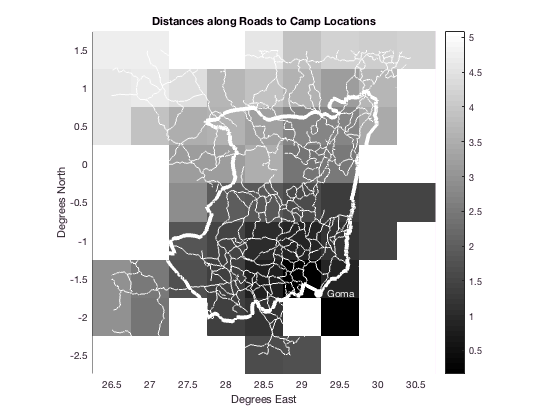

load 'DistToCamp.mat';
clf; figure; hold on;

% Plot Distance Heat Map
D = reshape([DistToCamp(:,1)],9,9);
imagesc(Grid.Lon, Grid.Lat, D);

% Plot Roads in Nord-Kivu Box
for i = 1:size(s_Roads_NK,1);
    plot(s_Roads_NK(i).Lon, s_Roads_NK(i).Lat, '-', 'Color', [1 1 1]);
end
hold on;

% Plot Nord-Kivu Boundary
plot(s_Adm2(32).Lon, s_Adm2(32).Lat, '-w', 'LineWidth', 4);

% Plot Goma, Capital City and Location of UNHCR Sub-Office
plot(s_Cities(10).Lon, s_Cities(10).Lat, '.w', 'MarkerSize', 30)
text(s_Cities(10).Lon+.1, s_Cities(10).Lat, 'Goma', 'Color', 'w')

% Formatting
title('Distances along Roads to Camp Locations'); axis equal; xlabel('Degrees East'); ylabel('Degrees North');
axis([26.5 30.5 -2.5 1.5]); colorbar; colormap('gray');
axis xy; axis equal; axis square; axis tight;